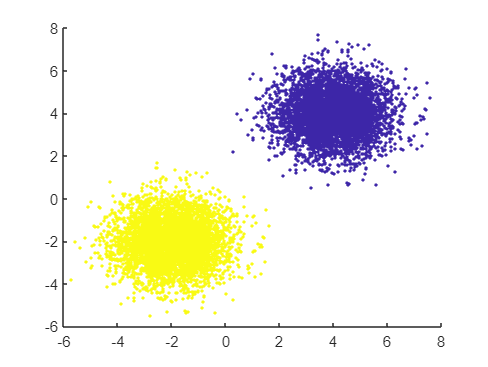

rng('default');  % For reproducibility
X = [gallery('normaldata',[5000 2],120)-2; ...
    gallery('normaldata',[5000 2],120)+4];
y = [ones(5000,1);-1*(ones(5000,1))];
scatter(X(:,1),X(:,2),5,y,'filled')

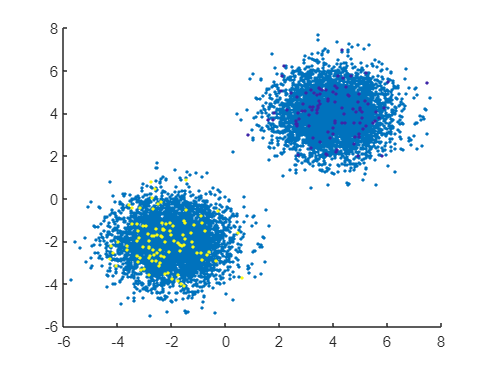

X_samp=[X(1:100,1:2); X(9901:10000,1:2)];
y_samp=[y(1:100); y(9901:10000)];
scatter(X(:,1),X(:,2),5,'filled')
hold on 
scatter(X_samp(:,1),X_samp(:,2),5,y_samp,'filled')
hold off

X_unlabeld=X(101:9900,1:2);

D_samp=zeros(200,9800);
for i=1:200
    for j=1:9800
        D_samp(i,j)=norm(X_samp(i,:)-X_unlabeld(j,:));
    end
end

D=zeros(9800,9800);
for i=1:9800
    for j=1:9800
        D(i,j)=norm(X_unlabeld(i,:)-X_unlabeld(j,:));
        D(j,i)=D(i,j);
    end
end

W_lab=exp(D_samp);
W=exp(D);